circular segment

If the cylindrical hull is submerged by length $h$ (the *draft* of the hull) the cross-sectional area below the waterline, $a$, is 


$$v = (L)\cdot \left( R^2\arccos\left(1-\frac{d}{R}\right) - \left(R-d\right)\sqrt{R^2-\left(R-d\right)^2}\right)$$


(see [circular segement](https://en.wikipedia.org/wiki/Circular_segment))

The displaced volume is the product of $a$ and the hull length.

At equilibirium


$$m_{usv} = m_{displacement}$$



$$m_{usv} = a \cdot l \cdot \rho_{water}$$


function b = usv_balance(h)
    rho_water = 1000;
    r = 0.213;
    l = 5; 
    a = r^2*acos(1-h/r) - (r-h).*sqrt(r^2-(r-h).^2);
    v = 2*a*l;
    m_displaced = v*rho_water;
    m_usv = 200;
    b = m_usv - m_displaced;
end


Test

usv_balance(0.1)

ans = -54.9199

h_zero = fzero(@usv_balance, 0.1)

h_zero = 0.0843

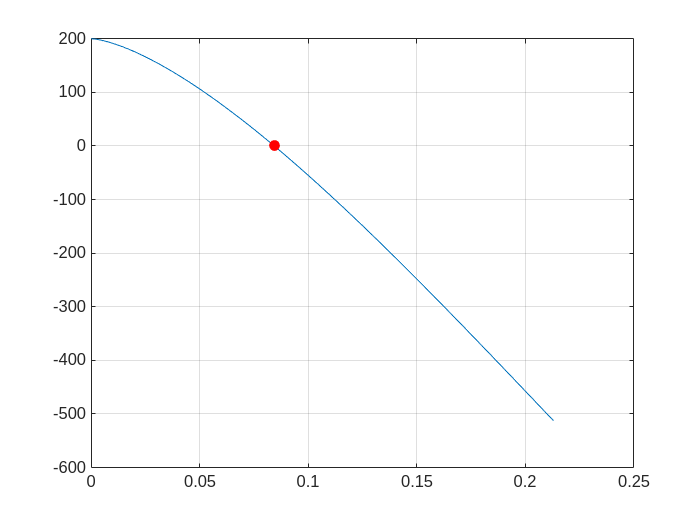

hh = linspace(0, 0.213);
bb = usv_balance(hh);
figure
plot(hh,bb)
hold on
plot(h_zero, usv_balance(h_zero), 'ro', 'MarkerFaceColor','r')
grid("on")